# NM-MILS计算渗流速度,Ultima-DTS

close all
clc
clear
warning off
format long

## 数据处理

### 1. 导入数据, 连续深度的温度-时间数据(加热段)

load flowCompute_20220925.mat
t = time_seconds;
temp = temperature;

### 2. 数据重新采样-直接抽稀

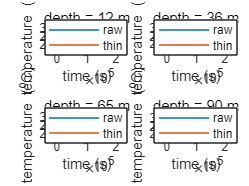

t_dt = downsample(t,90); %原始采样20 s
temp_dt = [];
for j = 1:size(temp,1)
    temp_dt(j,:) = downsample(temp(j,:),90);
end

% 查看抽稀效果
figure(1)
subplot(2, 2, 1)
plot(t,temp(47,:))
hold on
plot(t_dt,temp_dt(47,:))
hold off
title('depth = 12 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 2)
plot(t,temp(142,:))
hold on
plot(t_dt,temp_dt(142,:))
hold off
title('depth = 36 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 3)
plot(t,temp(256,:))
hold on
plot(t_dt,temp_dt(256,:))
hold off
title('depth = 65 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 4)
plot(t,temp(354,:))
hold on
plot(t_dt,temp_dt(354,:))
hold off
title('depth = 90 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on

### 3. 数据重新采样-平滑后抽稀

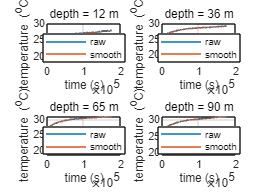

temp_sm = [];
for j = 1:size(temp,1)
    temp_sm(j,:) = smoothdata(temp(j,:),"lowess",[300 1800],...
    "SamplePoints",t);
end

% 查看平滑效果
figure(2)
subplot(2, 2, 1)
plot(t,temp(47,:))
hold on
plot(t,temp_sm(47,:))
hold off
title('depth = 12 m')
legend('raw','smooth',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 2)
plot(t,temp(142,:))
hold on
plot(t,temp_sm(142,:))
hold off
title('depth = 36 m')
legend('raw','smooth',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 3)
plot(t,temp(256,:))
hold on
plot(t,temp_sm(256,:))
hold off
title('depth = 65 m')
legend('raw','smooth',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 4)
plot(t,temp(354,:))
hold on
plot(t,temp_sm(354,:))
hold off
title('depth = 90 m')
legend('raw','smooth',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on

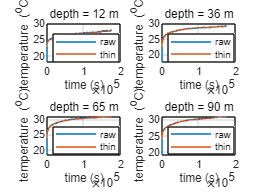

t_smdt = downsample(t,15); %原始采样20 s
temp_smdt = [];
for j = 1:size(temp_sm,1)
    temp_smdt(j,:) = downsample(temp_sm(j,:),15);
end

% 查看抽稀效果
figure(3)
subplot(2, 2, 1)
plot(t,temp(47,:))
hold on
plot(t_smdt,temp_smdt(47,:))
hold off
title('depth = 12 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 2)
plot(t,temp(142,:))
hold on
plot(t_smdt,temp_smdt(142,:))
hold off
title('depth = 36 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 3)
plot(t,temp(256,:))
hold on
plot(t_smdt,temp_smdt(256,:))
hold off
title('depth = 65 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 4)
plot(t,temp(354,:))
hold on
plot(t_smdt,temp_smdt(354,:))
hold off
title('depth = 90 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on

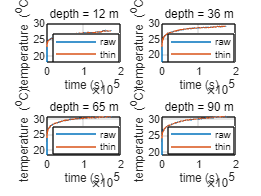

% 对比两种抽稀效果
figure(4)
subplot(2, 2, 1)
plot(t_dt,temp_dt(47,:))
hold on
plot(t_smdt,temp_smdt(47,:))
hold off
title('depth = 12 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 2)
plot(t_dt,temp_dt(142,:))
hold on
plot(t_smdt,temp_smdt(142,:))
hold off
title('depth = 36 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 3)
plot(t_dt,temp_dt(256,:))
hold on
plot(t_smdt,temp_smdt(256,:))
hold off
title('depth = 65 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on
subplot(2, 2, 4)
plot(t_dt,temp_dt(354,:))
hold on
plot(t_smdt,temp_smdt(354,:))
hold off
title('depth = 90 m')
legend('raw','thin',"Location","best")
xlabel('time (s)');
ylabel('temperature (^oC)')
grid on

## 最优化

### 1. 主程序

t_observed = t_dt;
% numIterations = size(temp_dt,1);
numIterations = 6;
parameter_estimated_all = zeros(numIterations, 3);
RMSE_all = zeros(numIterations, 1);

% 检查是否存在之前保存的变量
if exist('variables.mat', 'file')
    load('variables.mat');
    % 如果之前保存的变量数量与当前循环次数不匹配，重新初始化变量
    if size(parameter_estimated_all,1) ~= numIterations
        parameter_estimated_all = zeros(numIterations, 3);
        RMSE_all = zeros(numIterations, 1);
    end
end

% 将 objFun 函数所在的文件添加到工作进程
files = {'objFun.m'}; % 将包含 objFun 函数的文件名添加到此处
% 设置并行池，具体根据计算机硬件资源决定
parpool('local', 6)

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).

ans = 

 ProcessPool - 属性: 

            Connected: true
           NumWorkers: 6
                 Busy: false
              Cluster: 

addAttachedFiles(gcp, files);

% 初始化进度条
hbar = parfor_progressbar(numIterations,'Computing...'); 

try
    parfor i = 1:numIterations
        % 如果已经计算过，则跳过
        if RMSE_all(i) ~= 0
            continue;
        end
        
        temp_observed = temp_dt(i,:);

        % 定义参数初始值和目标函数
        parameter_process_0 = [5, 0.000000001, 0.000001];
        loss = @(parameter) objFun(parameter, t_observed, temp_observed);

        options = optimset('Display','off');
        options = optimset(options,'TolFun',1e-6,'TolX',1e-6);
        options = optimset(options,'MaxIter',6000);
        options = optimset(options,'MaxFunEvals',6000);
        options = optimset(options,'UseParallel', true); % 启用并行计算
                
        [parameter_estimated,RMSE] = fminsearch(loss,parameter_process_0,options);
        parameter_estimated_all(i,:) = parameter_estimated;
        RMSE_all(i) = RMSE; 
        
        % 更新进度条
        hbar.iterate(1);
        
        % 每隔30次循环保存一次变量
        if mod(i,30) == 0
            save('variables.mat', 'parameter_estimated_all', 'RMSE_all');
        end
    end
    
catch ME
    % 如果发生错误，则保存变量并关闭并行池
    save('variables.mat', 'parameter_estimated_all', 'RMSE_all');
    delete(gcp('nocreate'))
    rethrow(ME);
end

警告: 已达到正在使用的区间最大数目的限制。误差的近似范围为   2.2e+01。积分可能不存在，或者可能很难在数值上逼近要求的准确度。
> 位置：integralCalc/iterateScalarValued (第 372 行)
位置: integralCalc/vadapt (第 132 行)
位置: 


% 关闭并行池
delete(gcp('nocreate'))

% 保存最终变量
save('variables.mat', 'parameter_estimated_all', 'RMSE_all');

% 关闭进度条
close(hbar);

### 2. 查看观测温度曲线和计算曲线

for j = 1:numIterations
    a = parameter_estimated_all(j,1); % T_steady
    b = parameter_estimated_all(j,2);% r_divide_B
    c = parameter_estimated_all(j,3); % A
    d = besselk(0,b); % 第二类0阶贝塞尔函数
    temp_observed = temp_dt(j,:);
    for z = 1:size(t_observed,2)
        ti = t_observed(z);
        fun1 = @(s) exp(-s-((b^2)/4./s))./s;
        w_1(z) = integral(fun1,c/ti,inf);
        temp_computed(j,z) = a*w_1(z)/2/d;
    end
    temp_computed(j,1) = 0;
end

#### 查看某一深度结果

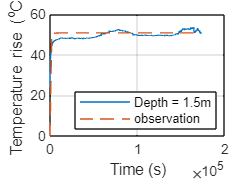

inter_depth = 6; % 1.5 m

figure(5)
for j = inter_depth 
        plot(t,temp(j,:));
        hold on
        plot(t_observed,temp_computed(j,:),'--');
        hold off
    end
hold off
grid on;
legend('Depth = 1.5m','observation','Depth = 60m','MILS',"Location","southeast")
xlabel('Time (s)');
ylabel('Temperature rise (^oC)'); 

### 3. 计算流速-不考虑热弥散效应,不考虑导热系数等参数的变化

thermal_conductivity = 2.0; %导热系数
rho_c_soil = 3600000; %土的密度乘以比热容
rho_c_water = 4200000; %水的密度乘以比热容

for j = 1:numIterations
    flow_rate(j) = parameter_estimated_all(j,2)*thermal_conductivity*sqrt(rho_c_soil)/rho_c_water/sqrt(parameter_estimated_all(j,3));
end

% 计算拟合误差
for j = 1:numIterations
    processing_1 = temp_dt(j,:);
    processing_2 = temp_computed(j,:);
    processing_3 = temp_dt(j,36:end);
    processing_4 = temp_computed(j,36:end);
    error.fit_part(j) = sqrt(sum((processing_4-processing_3).^2)/size(processing_3,2));
    error.fit(j) = sqrt(sum((processing_2-processing_1).^2)/size(processing_1,2));
end

### 保存结果

save result20230302_Ultima_3-48h.mat